data=readtable('titanic.csv')

data = 891×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex        Age    SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ________    ______    _______________________________________________________    __________    ___    _____    _____    __________    ______    __________    ________

         1            0          3       {'Braund, Mr. Owen Harris'                            }    {'male'  }     22      1        0             NaN      7.25    {0×0 char}     {'S'}  
         2   

data

data = 891×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex        Age    SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ________    ______    _______________________________________________________    __________    ___    _____    _____    __________    ______    __________    ________

         1            0          3       {'Braund, Mr. Owen Harris'                            }    {'male'  }     22      1        0             NaN      7.25    {0×0 char}     {'S'}  
         2   

x=data(:,6:10)

x = 891×5 table
    Age    SibSp    Parch      Ticket       Fare 
    ___    _____    _____    __________    ______

     22      1        0             NaN      7.25
     38      1        0             NaN    71.283
     26      0        0             NaN     7.925
     35      1        0       1.138e+05      53.1
     35      0        0      3.7345e+05      8.05
    NaN      0        0      3.3088e+05    8.4583
     54      0        0           17463    51.862
      2      3        1      3.4991e+05    21.075
     27      0        2      3.4774e+05    11.133
     14      1        0      2.3774e+05    30.071
      4      1        1             NaN      16.7
     58      0        0      1.1378e+05     26.55
     20      0        0             NaN      8.05
     39      1        5      3.4708e+05    31.275
     14      

y=data(:,2)

y = 891×1 table
    Survived
    ________

       0    
       1    
       1    
       1    
       0    
       0    
       0    
       0    
       1    
       1    
       1    
       1    
       0    
       0    
       0    
       1    


PohonKlasifikasi = fitctree(x,y)

PohonKlasifikasi =   ClassificationTree
           PredictorNames: {'Age'  'SibSp'  'Parch'  'Ticket'  'Fare'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 891


  Properties, Methods


rng(1); 
ValidasiSilang = fitctree(x,y,'CrossVal','on')

ValidasiSilang =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'Age'  'SibSp'  'Parch'  'Ticket'  'Fare'}
           ResponseName: 'Survived'
        NumObservations: 891
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


cabang = @(x)sum(x.IsBranch)

cabang = function_handle with value:
    @(x)sum(x.IsBranch)


mdlDefaultNumSplits = cellfun(cabang, ValidasiSilang.Trained)

mdlDefaultNumSplits =     47
    62
    54
    55
    55
    61
    51
    56
    64
    57


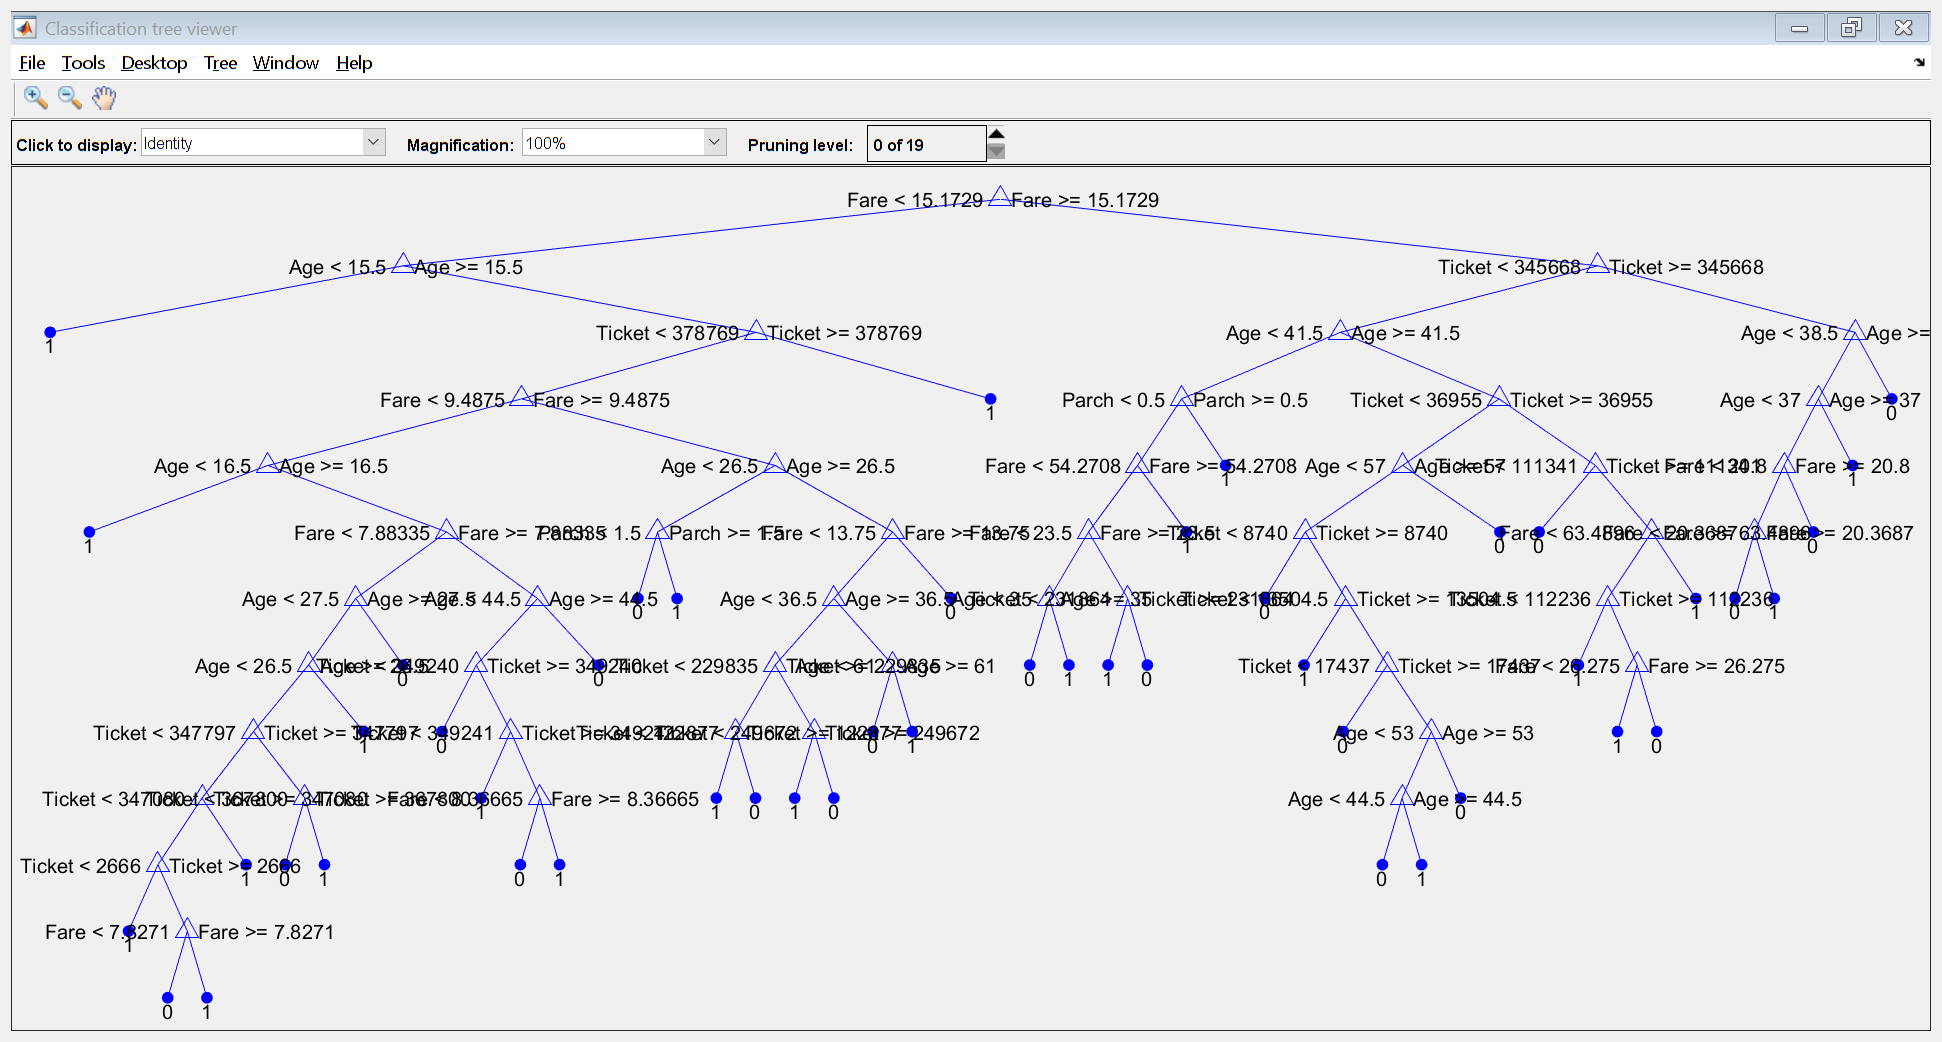

view(ValidasiSilang.Trained{1},'Mode','graph')